clear;
clc;

c = 3e8;
S = 29.982e12;
fs = 10000e3;
d = 1.95e-3;
f = 77e9;

numRx = 4;
numADCSamples = 200;
filestr = 'C:\Users\HuangOld\Desktop\临时\case2_static\adc_data_Raw_0.bin'; 
  
data = read1843Data(filestr, numADCSamples, numRx);

numFrame = 300;
numChirp = size(data,2)/numADCSamples;
numChirpPerFrame = numChirp/numFrame; 


theta = 90 / 180 * pi;
theta2 = 90 / 180 * pi;
dt = d * cos(theta) / c;
dt2 = d * cos(theta2) / c;

theta_comp = complex(cos(2 * pi * dt * f), sin(2 * pi * dt * f));
theta_comp2 = complex(cos(2 * pi * dt2 * f), sin(2 * pi * dt2 * f));

targData = data(1, :) + theta_comp * (data(2, :) + theta_comp * (data(3, :) + theta_comp * data(4, :)));
targData2 = data(1, :) + theta_comp2 * (data(2, :) + theta_comp2 * (data(3, :) + theta_comp2 * data(4, :)));
targData = reshape(targData, numADCSamples, numChirpPerFrame, []);
targData2 = reshape(targData2, numADCSamples, numChirpPerFrame, []);
disp(size(targData))

   200   128   300



% rangeWin = hamming(numADCSamples);
% rangeResult = targData .* repmat(rangeWin, 1, size(targData,2));
rangeResult = fftshift(fft(targData, [], 1), 1);
rangeResult = reshape(rangeResult, numADCSamples, []);
rangeResult2 = fftshift(fft(targData2, [], 1), 1);
rangeResult2 = reshape(rangeResult2, numADCSamples, []);
disp(size(rangeResult))

         200       38400




rangeRes = (c*fs) / (2*S*numADCSamples);
rangeTicks = rangeRes .* ((-numADCSamples/2):(numADCSamples/2-1));
rangeTicks = round(rangeTicks,2);

disp(rangeRes)

    0.2502



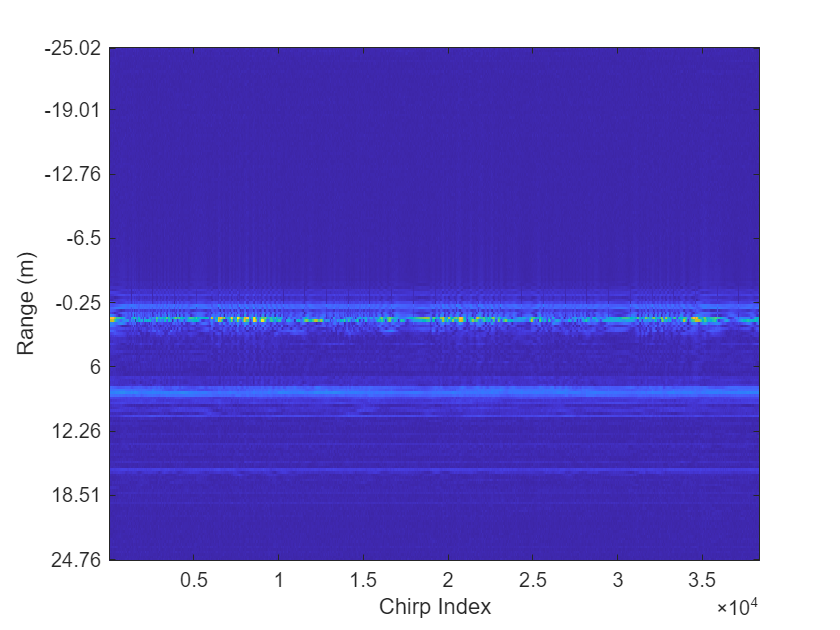


figure(1);
imagesc(abs(rangeResult));

yidxs = floor(linspace(1,length(rangeTicks),9));
yticks(yidxs);
yticklabels(string(rangeTicks(yidxs)))
xlabel('Chirp Index');
ylabel('Range (m)');

phases = angle(rangeResult);
phases2 = angle(rangeResult2);
displacements = zeros(numADCSamples, numChirp);
displacements2 = zeros(numADCSamples, numChirp);
for i = 1:numADCSamples
    displacements(i, :) = calcDisplacement(phases(i, :), numChirp, c);
    displacements2(i, :) = calcDisplacement(phases2(i, :), numChirp, c);
end

vars = zeros(numADCSamples * numADCSamples, 3);
for i = 100:numADCSamples
    for j = (i + 1):numADCSamples
        vars((i - 1) * numADCSamples + j, 1) = var(displacements(i, :) - displacements(j, :));
        vars((i - 1) * numADCSamples + j, 2) = i;
        vars((i - 1) * numADCSamples + j, 3) = j;
    end
end

vars = sortrows(vars, 1, 'descend');
% disp(vars(1:10, :));

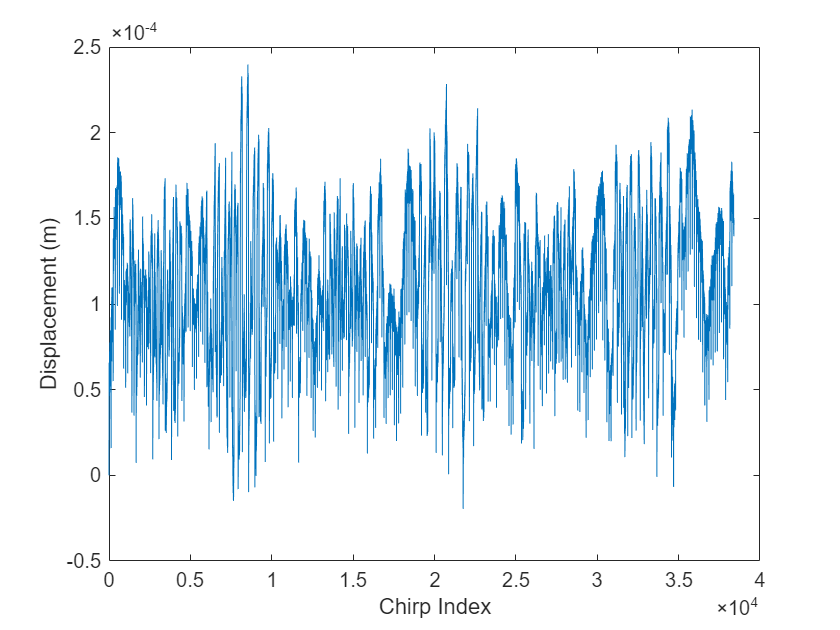

figure(2);
xlabel('Chirp Index');
ylabel('Displacement (m)');

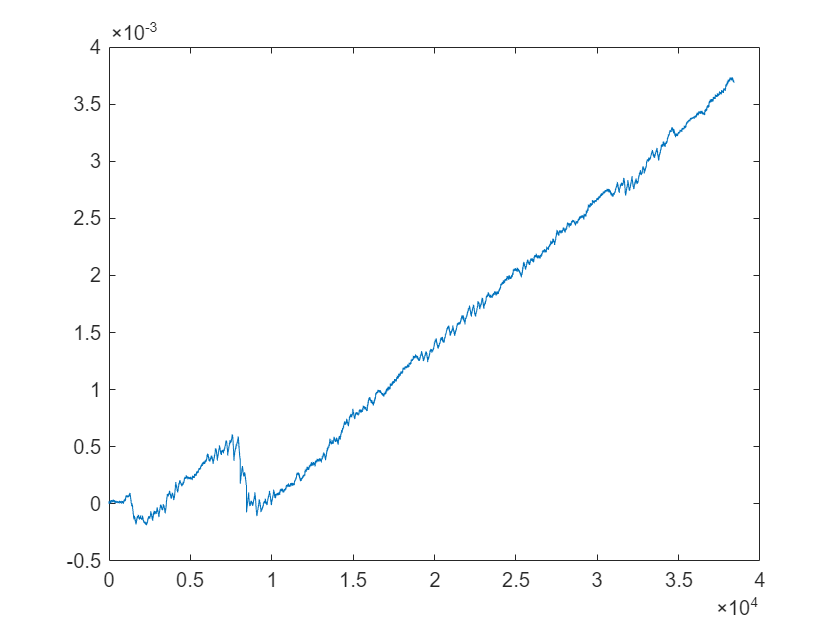

plot(1:numChirp, displacements(102, :));

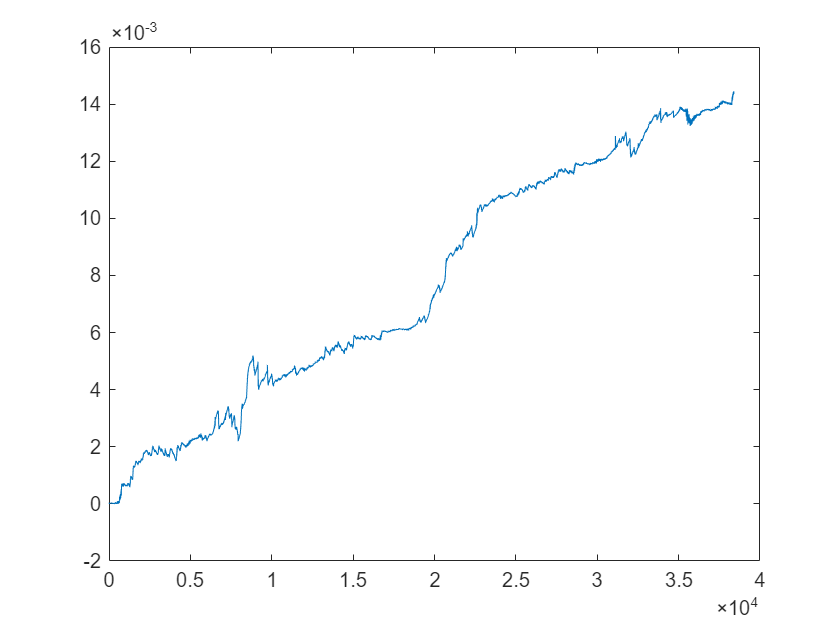

figure(3);
xlabel('Chirp Index');
ylabel('Displacement (m)');
plot(1:numChirp, displacements(103, :));

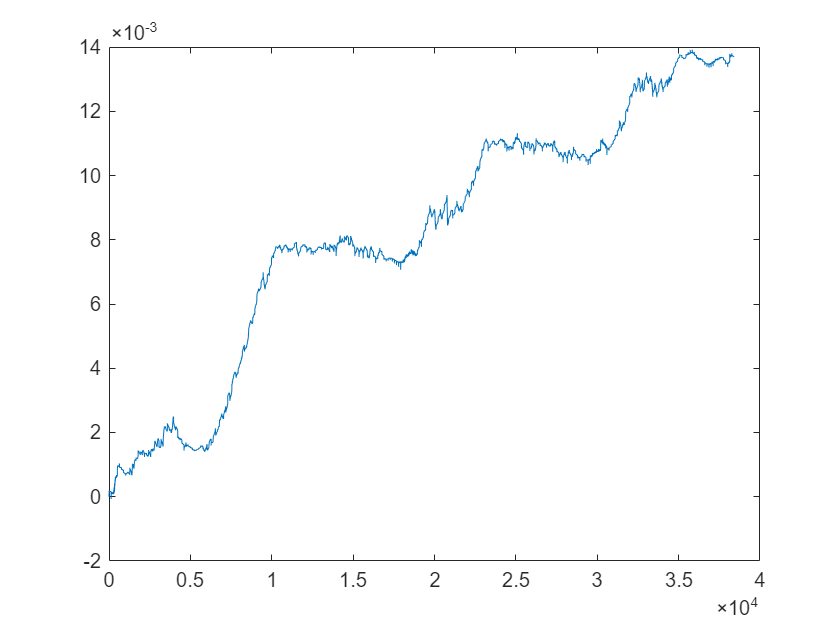

figure(4);
xlabel('Chirp Index');
ylabel('Displacement (m)');
plot(1:numChirp, displacements(104, :));

function [displacement] = calcDisplacement(phases, numChirp, c)
    displacement = zeros(1, numChirp);
    displacement(1) = 0;

    for i = 2:numChirp
        if abs(phases(i - 1) - phases(i)) < pi / 4
            displacement(i) = displacement(i - 1) + phases(i) - phases (i - 1);
        elseif abs(phases(i - 1) - phases(i)) < 7 * pi / 4
            displacement(i) = displacement(i - 1);
        elseif phases(i - 1) > phases(i)
            displacement(i) = displacement(i - 1) + phases(i) - phases (i - 1) + 2 * pi;
        else
            displacement(i) = displacement(i - 1) + phases(i) - phases (i - 1) - 2 * pi;
        end
    end
    displacement = displacement .* (c / 4 / pi / 77e9);
%    displacement = displacement .* (c / 4 / pi / 77e9) * (1 / .192);
end